# Experimento das rodas - Selecionado

### Baseado no bode e no experimento exp2_rodas 

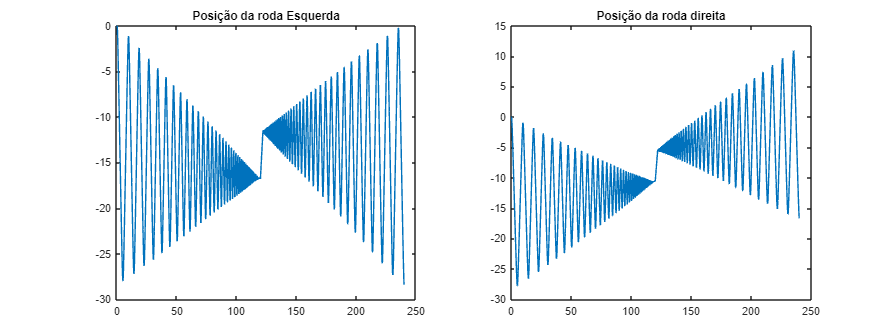

clear
load("exp2_rodas.mat")

Vmax = 7.4;
pwm = 1.0;
u = u/255 ;
yr = yr / (Vmax * pwm) / (30 * 4 * 7) * 2 * pi;
yl = yl / (Vmax * pwm) / (30 * 4 * 7) * 2 * pi;

figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]);
clear pos

subplot(1,2,1)
plot(t, yl)
title("Posição da roda Esquerda")
subplot(1,2,2)
plot(t, yr)
title("Posição da roda direita")

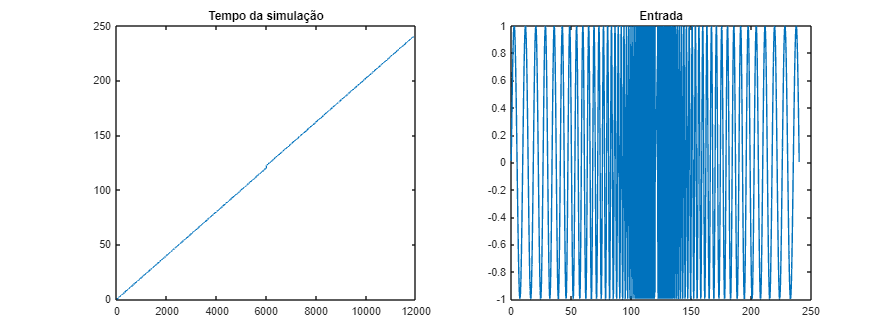

figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]);
clear pos

subplot(1,2,1)
plot(t)
title("Tempo da simulação")
subplot(1,2,2)
plot(t, u)
title("Entrada")

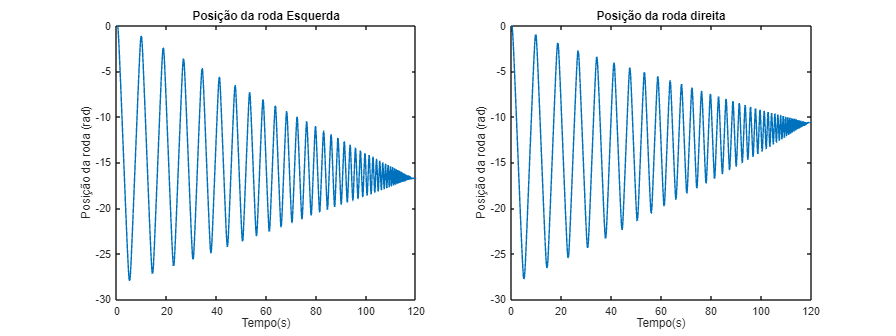

idx = t>0 & t<120;
% idx = t>122 & t<240;
% idx = t>0 & t<240;

figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]);
clear pos

subplot(1,2,1)
plot(t(idx), yl(idx))
title("Posição da roda Esquerda")
xlabel('Tempo(s)')
ylabel('Posição da roda (rad)')

subplot(1,2,2)
plot(t(idx), yr(idx))
title("Posição da roda direita")
xlabel('Tempo(s)')
ylabel('Posição da roda (rad)')

ts = 0.01;
figure
dados = iddata(yl(idx), -u(idx), ts);
G = tfest(dados, 1, 0)

G =
 
  From input "u1" to output "y1":
      16.66
  -------------
  s + 4.824e-11
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                           
Estimated using TFEST on time domain data "dados".
Fit to estimation data: 76.51%                    
FPE: 1.632, MSE: 1.631                            
 
Model Properties


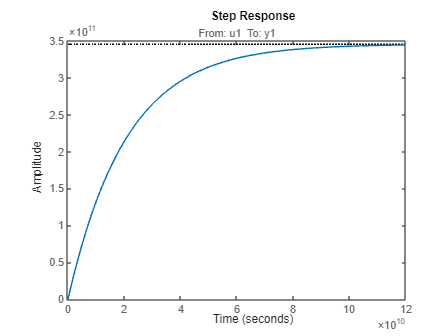

step(G)

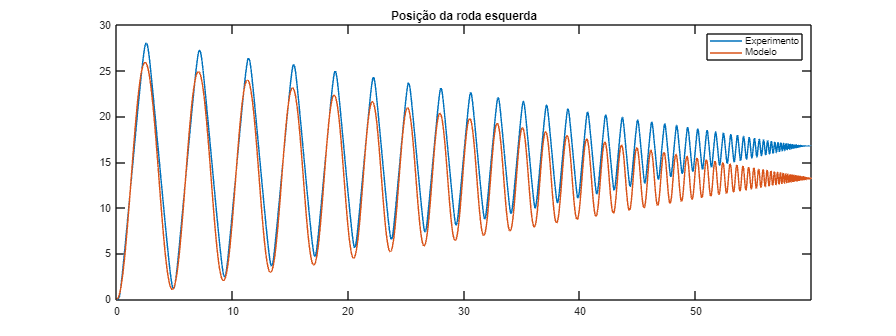

tt = 0:ts:length(u(idx))*ts-ts;
% idx = (length(tt)*7/8:length(tt));

y = lsim(G, u(idx), tt);
figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]);
clear pos

plot(tt, -yl(idx))
title("Posição da roda esquerda")
hold on
plot(tt, y)
xlim([tt(1) tt(end)])
legend("Experimento", "Modelo")

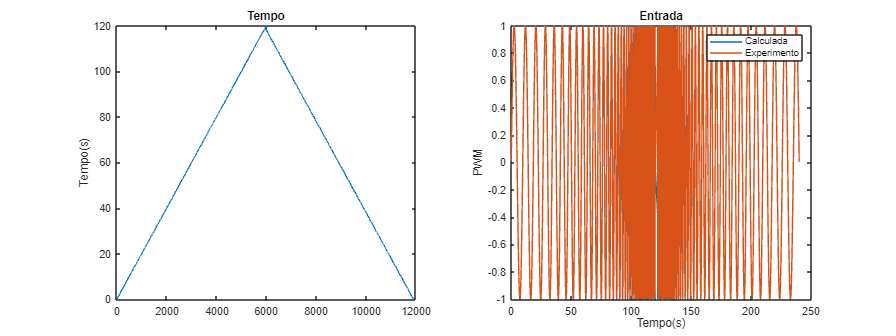


mT = 120*1000;
T = 120;
ti = zeros(length(t), 1);
f0 = 0.1;
f1 = 20;

for i = 2:length(t)
    ti(i) = mod((t(i) - t(1))*1000 + mT, 2 * mT) - mT;
end
ti = abs(ti) / 1000;

pwm = (1 * sin(-2 * pi * f0 * f1 * T / (f1 - f0) * log(1 - (f1 - f0) / (f1 * T) * ti)));

figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]);
clear pos

subplot(1,2,1)
plot(ti)
title('Tempo')
ylabel('Tempo(s)')
subplot(1,2,2)
plot(t, pwm)
title('Entrada')
hold on 
plot(t, u)
xlabel('Tempo(s)')
ylabel('PWM')
legend('Calculada', 'Experimento')

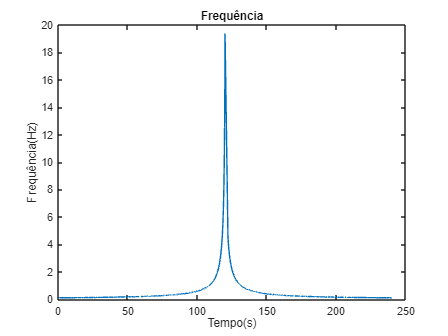


freq = ones(length(ti), 1);
for i=1:length(ti)
    freq(i) = f0 * f1 * T / ((f0 - f1) * ti(i) + f1 * T);
end

% freq = freq / max(freq);
% yl = yl - min(yl);
% yl = yl / max(yl);
% idx = (1:length(ti));
% freq = freq(idx);
% min(freq)
% max(freq)

figure 
plot(t, freq)
title('Frequência')
xlabel('Tempo(s)')
ylabel('Frequência(Hz)')

% hold on
% figure
% plot(t(idx), yl(idx))

clear mT T f0 f1 i

t1 = t(idx);
u1 = u(idx);
yl1 = yl(idx);
yr1 = yr(idx);
freq1 = freq(idx);

toRPM = 60 / (7 * 4 * 30);

rvel = gradient(yr1) ./ gradient(t1);
rvel = rvel * toRPM;
lvel = gradient(yl1) ./ gradient(t1);
lvel = lvel * toRPM;

max(u1)

ans = 0.9961

max(lvel)

ans = 0.4910

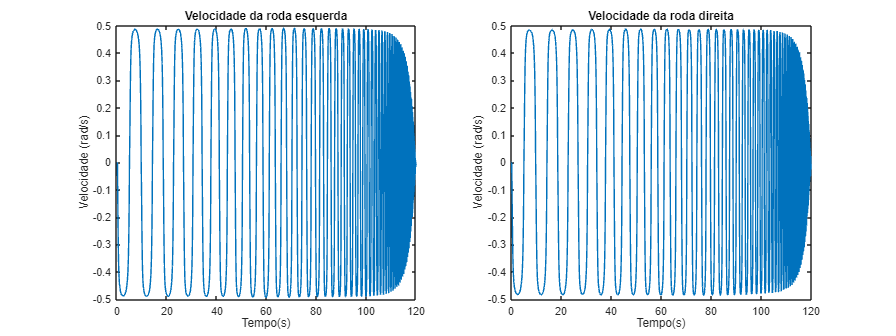


figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]);
clear pos

subplot(1,2,1)
plot(t1, lvel)
title("Velocidade da roda esquerda")
xlabel('Tempo(s)')
ylabel('Velocidade (rad/s)')

subplot(1,2,2)
plot(t1, rvel)
title("Velocidade da roda direita")
xlabel('Tempo(s)')
ylabel('Velocidade (rad/s)')

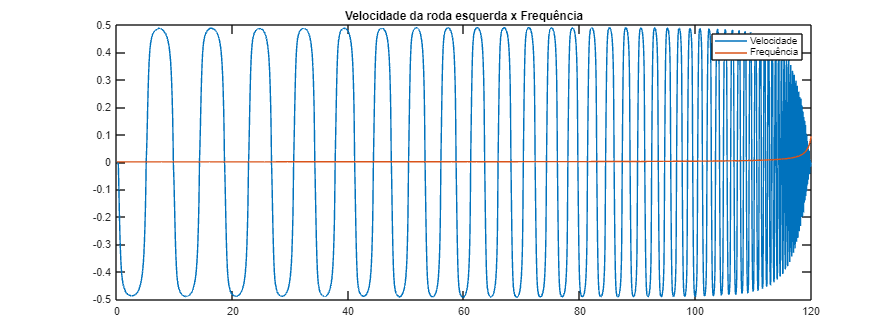


figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]);
clear pos

x = [t1(1) t1(end)];

plot(t1, lvel)
title("Velocidade da roda esquerda x Frequência")
hold on
plot(t1, freq1/200) 
% plot(x, [1 1]*max(lvel))
% plot(x, [1 1]*(3.4639))
% plot([1 1]*(116.46), [-5 20])
legend(["Velocidade" "Frequência"])


Declvel = 20*log10(abs(lvel));
MDecvel = max(Declvel)

MDecvel = -6.1154

M_3Decvel = max(Declvel) - 3

M_3Decvel = -9.1154

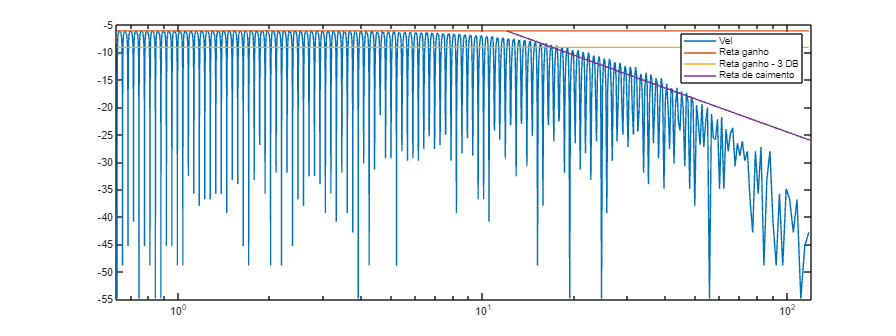


freq_rad = 2*pi*(freq1);

figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]);
clear pos

semilogx(freq_rad, Declvel)
hold on
semilogx([freq_rad(1) max(freq_rad)], [1 1]*MDecvel) 
semilogx([freq_rad(1) max(freq_rad)], [1 1]*(M_3Decvel)) 
semilogx([2*pi*(1.91) 2*pi*(19.1)], [MDecvel MDecvel-20]) 
legend(["Vel" "Reta ganho" "Reta ganho - 3 DB" "Reta de caimento"])

ts = 0.01;

idx = t>0 & t<240;
t1 = t(idx);
u1 = u(idx);
yl1 = yl(idx);
yr1 = yr(idx);

toRPM = 60 / (7 * 4 * 30);

rvel = gradient(yr1) ./ gradient(t1);
rvel = rvel * toRPM;
lvel = gradient(yl1) ./ gradient(t1);
lvel = lvel * toRPM;

max(lvel) / max(u1)

ans = 0.4947


left = iddata(lvel, u1, ts);
% G_l = tfest(left, 1, 0);
s = tf("s");
K = -max(lvel) / max(u1);
tau_p = 1/18;

### Valores Ideais:

- K = -1.91;

- $\tau$ = 0.05.

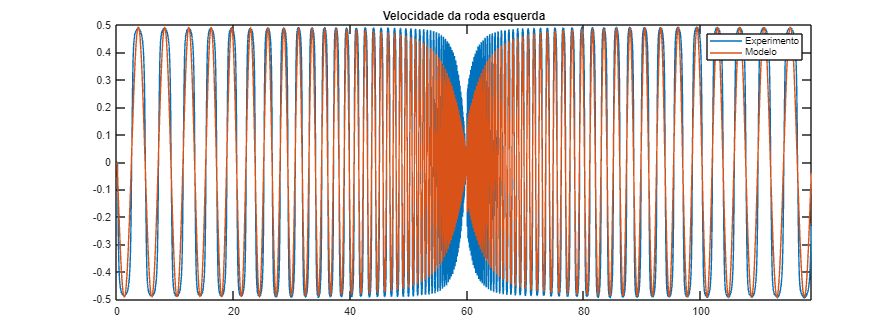

G_l = K*1/(tau_p*s+1);

tt = 0:ts:length(u1)*ts-ts;
% idx = (length(tt)*7/8:length(tt));
idx = (1:length(tt));

y = lsim(G_l, u1, tt);
figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]);
clear pos

plot(tt(idx), lvel(idx))
title("Velocidade da roda esquerda")
hold on
plot(tt(idx), y(idx))
xlim([tt(idx(1)) tt(idx(end))])
legend("Experimento", "Modelo")

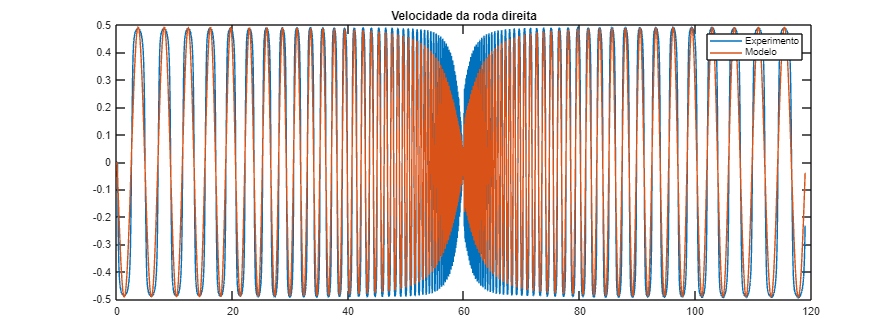

rigth = iddata(rvel, u1, ts);
G_r = tfest(rigth, 2, 0);
G_r = K*1/(tau_p*s+1);

y = lsim(G_r, u1, tt);
figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]);
clear pos

plot(tt, lvel)
title("Velocidade da roda direita")
hold on
plot(tt, y)
legend("Experimento", "Modelo")

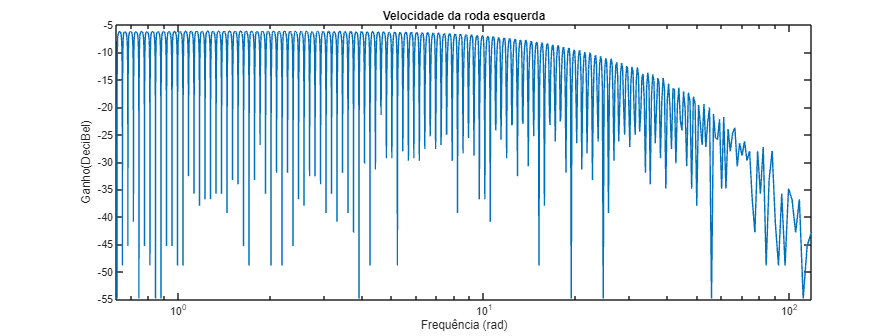

figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]);
clear pos

semilogx(freq_rad, Declvel)
title("Velocidade da roda esquerda")
xlabel("Frequência (rad)")
ylabel("Ganho(DeciBel)")


W = linspace(min(freq_rad), max(freq_rad), length(freq_rad));
[MAG,PHASE,W] = bode(G_l, W);
MAG = squeeze(MAG);
MAG1 = 20*log10(MAG);

G_l = G_l * tf(1, [1/(18.5*3) 1])

G_l =
 
            -0.4947
  ----------------------------
  0.001001 s^2 + 0.07357 s + 1
 
Continuous-time transfer function.
Model Properties


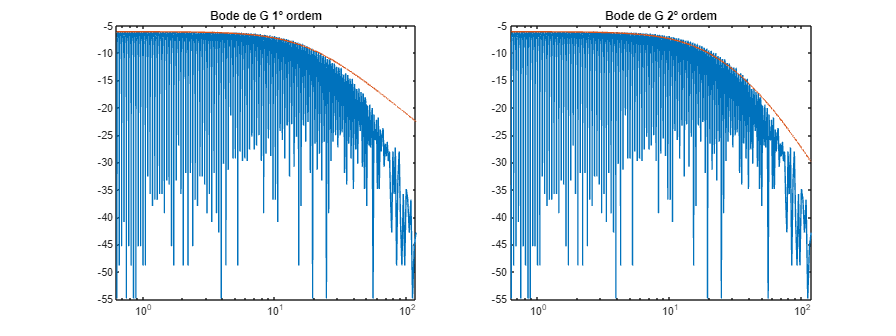

% G_l = tf(K, [1/20 1])
[MAG,PHASE,W] = bode(G_l, W);
MAG = squeeze(MAG);
MAG2 = 20*log10(MAG);


figure
pos = get(gcf, 'Position');
set(gcf, 'Position', [pos(1) pos(2) pos(3)*2 pos(4)]);
clear pos

subplot(1,2,1)
semilogx(freq_rad, Declvel)
hold on
semilogx(W,MAG1)
xlim([min(freq_rad), max(freq_rad)])
title("Bode de G 1º ordem")

subplot(1,2,2)
semilogx(freq_rad, Declvel)
hold on
semilogx(W,MAG2)
xlim([min(freq_rad), max(freq_rad)])
title("Bode de G 2º ordem")

G_r

G_r =
 
     -0.4947
  -------------
  0.05556 s + 1
 
Continuous-time transfer function.
Model Properties


zpk(G_r)

ans =
 
  -8.9048
  -------
  (s+18)
 
Continuous-time zero/pole/gain model.
Model Properties


K_rodas = ans.K

K_rodas = -0.4947

tau = -1/ans.P{1}

tau = 0.0556